[target, ref] = recorded_samples();

cutoff = 400;
fs = 48000;

target = highpass(target, cutoff, fs);
ref = highpass(ref, cutoff, fs);


step_sizes = [.001, .005, .01, .05, .1, .5, .9];
ir_lens = [128, 256, 512, 1024];

N = length(ir_lens);
S = length(step_sizes);
n_iter = 20;
mses = zeros(N, S, n_iter);
preds = zeros(N, S, length(target));

out_wav = zeros(length(target), 1);
best_filt = FxLMS(ref, target, panel_ir, filter_order, .05);

min_mse = 100;
min_i = 0;
min_j = 0;

for i = 1:N
    ir_len = ir_lens(i);
    source_to_ref_cm = 2;

    panel_ir = clipped_irs(ir_len, source_to_ref_cm);

    panel_ir = highpass(panel_ir, cutoff, fs);


    filter_order = ir_len * 2;

    for j = 1:length(step_sizes)
    
        step_size = step_sizes(j);
    
        fxlms = FxLMS(ref, target, panel_ir, filter_order, step_size);
        fxlms.gpu = false;
        [pred_i, mses_i] = fxlms.learn(n_iter);
    
        mses(i, j, :) = mses_i;
        preds(i, j, :) = pred_i;
        
        disp(mses_i)

        if mses_i(end) < min_mse
            min_mse = mses_i(end);
            min_i = i;
            min_j = j;
            out_wav = fxlms.ref_filt;
            best_filt = fxlms;
        end
    end

    disp('');

end

   1.0e-07 *

    0.7255    0.4040    0.3140    0.2681    0.2402    0.2216    0.2086    0.1992    0.1922    0.1869    0.1828    0.1796    0.1771    0.1752    0.1736    0.1723    0.1713    0.1704    0.1697    0.1692

   1.0e-07 *

    0.3707    0.1528    0.1289    0.1222    0.1198    0.1188    0.1183    0.1179    0.1176    0.1174    0.1171    0.1169    0.1167    0.1166    0.1164    0.1163    0.1161    0.1160    0.1159    0.1157

   1.0e-07 *

    0.2585    0.1042    0.0981    0.0970    0.0965    0.0961    0.0958    0.0956    0.0954    0.0952    0.0950    0.0948    0.0947    0.0946    0.0944    0.0943    0.0942    0.0941    0.0940    0.0939

   1.0e-07 *

    0.1119    0.0639    0.0635    0.0633    0.0631    0.0630    0.0629    0.0628    0.0628    0.0627    0.0627    0.0626    0.0626    0.0626    0.0625    0.0625    0.0625    0.0625    0.0625    0.0624

   1.0e-08 *

    0.8195    0.5595    0.5572    0.5557    0.5548    0.5541    0.5536    0.5531    0.5528    0.5525    0.5523    0.5522  

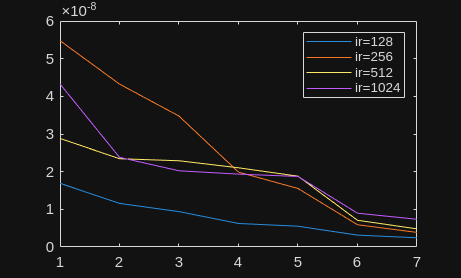

figure
plot(mses(1, :, end))
hold on
plot(mses(2, :, end))
hold on
plot(mses(3, :, end))
hold on
plot(mses(4, :, end))
legend("ir=128", "ir=256", "ir=512", "ir=1024")

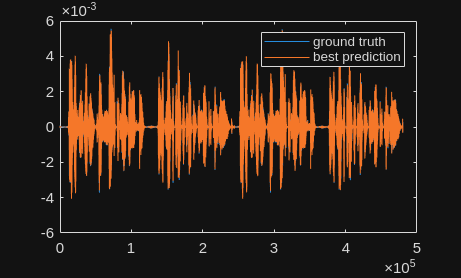

figure
plot(target)
hold on
plot(squeeze(preds(min_i, min_j, :)));
legend("ground truth", "best prediction")
hold off

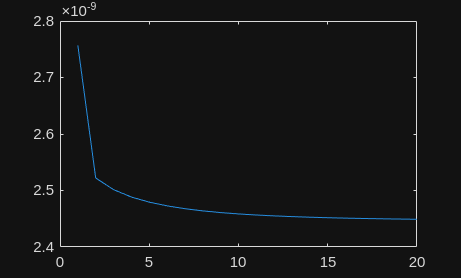

figure
plot(squeeze(mses(min_i, min_j, :)))

min_i % ir_length

min_i = 1

min_j % step size

min_j = 7

function save_cancel_clip(wav, filename)
    [a, fs] = arthur();
    wav = wav(1:length(a));

    disp(size(a))
    disp(size(wav))
    
    y = ([wav, a]);

    audiowrite([filename, '.wav'], y, fs);
    audiowrite([filename, '_no_cancel.wav'], [zeros(length(a), 1), a], fs);
end

save_cancel_clip(out_wav, 'fxlms')

      238834           1

      238834           1



pwd()

ans = '/home/yarnbowser'